#  Práctica de sustitución 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Una comprensión profunda de la integral como antiderivada sólo puede llevarte hasta cierto punto. Al igual que con las derivadas, existen reglas de integración que también se pueden construir mediante la combinación de funciones. El método de sustitución que se analizará en este guión en vivo se aplica a casi todas las integrales que jamás calcules. De hecho, es probable que incluso olvides que lo estás aplicando en algunos casos porque su uso resultará muy natural. 

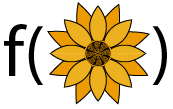

El método de sustitución le permite reemplazar una integral complicada por una más simple. 

** Antes de comenzar: **

 Este script en vivo está diseñado para usarse con el código oculto. En la pestaña ** Ver ** de la barra de herramientas de MATLAB, en la sección ** Ver **, seleccione ** Ocultar código **.  Alternativamente, seleccione ** Ocultar código ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [Rampa de entrada de MATLAB](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

clear gPrime uPrime NewMeasure Measure g fa fb fc fu f MyFun MyAnswer LastFive
 

## ** Practica el uso de la sustitución **

Reescribe cada una de las siguientes integrales en términos de la nueva variable proporcionada por la función de sustitución, $\displaystyle \int f(g(x))g'(x)dx = \int f'(g)\; dg.$. Luego resuelve la integral. 

### ** Ejercicio 1 **

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ donde $g(x) = 3x^5$

Primero, encuentra la derivada de $g(x)$ con respecto a $x$: 

gPrime = @(x) x; 

¿Cuál será la nueva medida $dg$ en términos de $x$ y $dx$? 

NewMeasure = @(x,dx)dx; 

Si definimos $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\; dg$ , ¿qué es $f(g)$ ? 

fa = @(g) g; 

Calcula la función $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$. 

Answer = @(x,C) x;
Check1a(gPrime,fa,NewMeasure,Answer);
 

  ** Nota: ** En muchos libros de texto es común usar una variable $u$ en lugar de la variable $g$ o incluso llamar a este método $u$ -sustitución. 

###  Ejercicio 2 

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ donde $u(t) = \frac{1+t}{t^2+5}$ 

Calcula la derivada $u'(t)$. 

uPrime = @(t) t; 

Calcula los nuevos límites y la nueva medida para la integral en términos de $u$. 

ua = 1;
gb = 3;
NewMeasure = @(t,dt)dt; 

Si definimos $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot du$ , ¿qué es $f(u)$ ? 

f = @(u)u; 

Calcula la función $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$. 

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("This is a definite integral. Your solution should be a number.")
    else
        rethrow(ME)
    end
end
Check1b(uPrime,f,ua,gb,NewMeasure,Answer);
 

### ** Ejercicio 3 **

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ donde $q(r) = e^r-17$ 

Recuerda que $e^x$ se escribe como `exp(x)` en MATLAB. 

gPrime = @(r) r;
NewMeasure = @(r,dr)dr; 

Si definimos $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \; dq$ , 

fc = @(q) q;
Answer = @(r,C) r;
Check1c(gPrime,fc,NewMeasure,Answer);
 

### ** Ejercicio 4 **

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ donde $g(w) = 1+w^2$. 

gPrime = @(w) w;
ga = -1;
gb = 2;
measure = @(w,dw)dw; 

Recuerde que $\ln(g)$ está escrito `log(g)` en MATLAB. 

Si definimos $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot dg,$

fb = @(g) g; 

Este resultado aún no es computable inmediatamente, así que hagamos otra sustitución con $u(g) = \ln(g)$. 

Si definimos $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot du,$

ua = -1;
ub = 2; 

Calculando $du$ como una función de $g$ : 

nextMeasure = @(g,dg)dg;
fu = @(u) u; 

Juntando todo, calcula el resultado: 

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("This is a definite integral. Your solution should be a number.")
    else
        rethrow(ME)
    end
end
Check1d(gPrime,fb,ga,gb,measure,nextMeasure,ua,ub,fu,Answer);
 

##  Practica integrales de sustitución aleatoria 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear ErrorCount TotSubProbs TotAttempts adjustcount LastFive MyFun VarChoice
syms t r x z C              % Declarar variables simbólicas
VarOpts = [t r x z];        % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;             % Inicializar un recuento de errores
TotSubProbs = 0;            % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;            % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;            % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);      % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Values initialized for Substitution Practice.") 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotSubProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [MyFun,VarChoice] = GenProbType(VarOpts,1);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    TotSubProbs = TotSubProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Run this section 

MyAnswer = r;     % Solución definida por el usuario, valor predeterminado r
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotSubProbs, ...
    AdjustCount,MyFun,VarChoice,MyAnswer,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section 

Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(TotSubProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)

###  Aplicación de práctica 

Puede practicar en la aplicación Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debes configurar el tipo de problema como "Sustitución" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[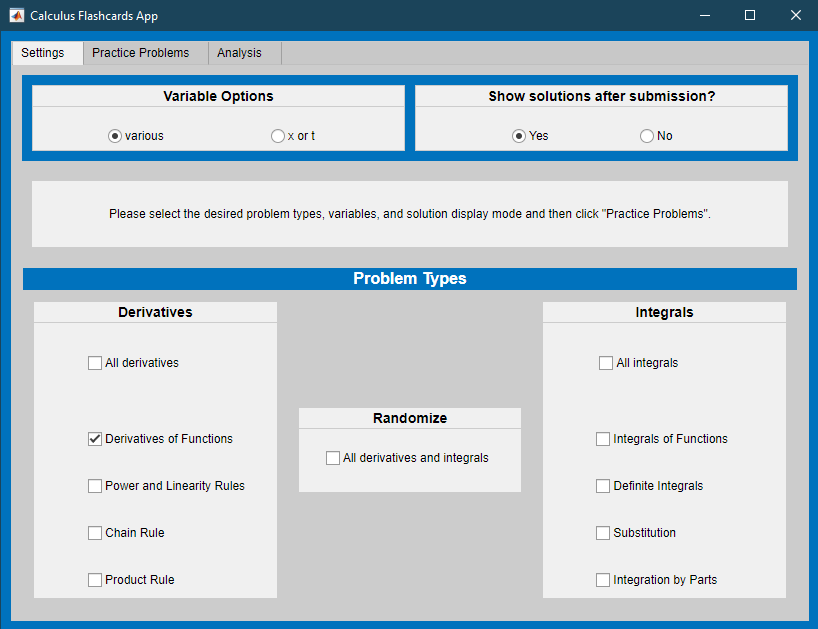](matlab: CalculusFlashcards)

[Aplicación Tarjetas didácticas de cálculo](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

% % Práctica de funciones generadoras de problemas

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% AnalyzeResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% Check1 genera respuestas correctas al diferenciar y actualizar
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ​​los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
switch probType
    case 1 % derivada simple
        syms f(x) g(x) x
        [f(x),prevFuncType] = GenFunDiff([1 3],x,[1 10],0);
        g(x) = GenFunDiff([1 5],x,[5 10],prevFuncType);
        myFun = diff(f(g(varChoice)),varChoice);
        % Mostrar el problema integral
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t+d);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t+d);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t+d);
    case 10
        f(t) = a*cos(b*t+d);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t+d);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t+d);
end
myFunc = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
            [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

** Soluciones del Ejercicio 1 **

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ donde $g(x) = 3x^5$

function Check1a(gp,fsub,newMeasure,soln)
syms C x g dx dg %#ok<NASGU>
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
measAns(x,dx) = gpans*dx;
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && isequal(newMeasure(x,dx),dx) && isequal(soln(x,C),x)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(x,dx) == measAns(x,dx),"Unknown","false");
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        displayFormula(['"Correct.  "' "dg/dx = gpans"])
    else
        disp("You do not have the correct function for g'(x).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(15*sin(3*x^5)*x^4,x) = correctAns"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end 

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ donde $u(t) = \frac{1+t}{t^2+5}$

function Check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u du dt a b %#ok<NASGU>
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
measAns = @(t,dt) gpans*dt;
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && isequal(newMeasure(t,dt),dt) && soln == 0
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = isAlways(newMeasure(t,dt) == measAns(t,dt),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        displayFormula(['"Correct.  "' "du/dt = gpans"])
    else
        disp("You do not have the correct function for u'(t).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "du = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(u) = fg"])
    else
        disp("You do not have the correct function for f(u)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the integral: "' "u(a) = ua" '" and "' "u(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound.")
    end
    if a4
        decimalAns = vpa(correctAns); %#ok<NASGU>
        displayFormula(['"Correct, the value of this integral is "' "correctAns = decimalAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Please try again.")
    end
end
end

 c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ donde $q(r) = e^r-17$ 

function Check1c(gp,fsub,newMeasure,soln)
syms C x r q dq dr %#ok<NASGU>
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
measAns = @(r,dr)gpans*dr;
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && isequal(newMeasure(r,dr),dr) && isequal(soln(r,C),r)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(r,dr)==measAns(r,dr),"Unknown","false");
    try
        a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    catch ME
        a4 = false;
        if ME.message == "Unrecognized function or variable 'q'."
            a4flag = "q";
        else
            rethrow(ME)
        end
    end
    if a1
        displayFormula(['"Correct.  "' "dq/dr = gpans"])
    else
        disp("You do not have the correct function for q'(r).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dq = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(q) = fg"])
    else
        disp("You do not have the correct function for f(q)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(exp(r)*cos(exp(r)-17),r) = correctAns"])
    elseif exist("a4flag","var") && a4flag == "q"
        displayFormula(['"The solution should be a function of "' "r" '" not "' "q"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end 

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ donde $g(w) = 1+w^2$. 

function Check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g u dg du dw a b %#ok<NASGU>
% Primera sustitución
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
gaVal = ut(-1);
gbVal = ut(2);
% Segunda sustitución
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
measAns = @(w,dw)gpans*dw;
meas2Ans = @(g,dg)diff(log(g),g)*dg;
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub(g),g) && ua == -1 && ub == 2 && isequal(newMeas1(g,dg),dg) && soln == 0 ...
        && isequal(newMeas2(g,dg),dg) && ua2 == -1 && ub2 == 2 && isequal(fusub(u),u)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = isAlways(newMeas1(w,dw) == measAns(w,dw),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = isAlways(newMeas2(g,dg) == meas2Ans(g,dg),"Unknown","false");
    a8 = isequal(fu(t),fusub(t));
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        displayFormula(['"Correct.  "' "dg/dw = gpans"])
    else
        disp("You do not have the correct function for g'(w).")
    end
    if a3
        displayFormula(['"Correct. The new measure for the first integral is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.   "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the first integral: "' "g(a) = ua" '" and "' "g(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the first integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the first integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the first integral.")
    end
    if a9 && a10
        displayFormula(['"You have the correct values for the bounds of the second integral: "' "u(a) = log(ua)" '" and "' "u(b) = log(ub)"])
    elseif ~a9 && ~a10
        disp("You have not calcuated the correct values for the bounds of the second integral.")
    elseif a9
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the second integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the second integral.")
    end
    if a7 && a8
        displayFormula(['"Correct. The new measure for the second integral is "' "du = measAns";...
            '" and the integrand is "' "f(u) = fu"])
    elseif a7 && ~a8
        disp("Correct measure, but incorrect integrand in the second integral.")
    elseif ~a7 && a8
        disp("Incorrect measure, but correct integrand in the second integral.")
    else
        disp("Incorrect measure and incorrect integrand in the second integral.")
    end
    if a4
        displayFormula(['"Correct, the value of this integral is "' "int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2])==correctAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~(a2&a3) ~a4 ~a5 ~a6 ~(a7&a8)])
        disp("Please try again.")
    end
end
end 